Defind f(t)

Ts=0.001;
T=3;

t=-T/2+Ts:Ts:T/2-Ts

t =    -1.4990   -1.4980   -1.4970   -1.4960   -1.4950   -1.4940   -1.4930   -1.4920   -1.4910   -1.4900   -1.4890   -1.4880   -1.4870   -1.4860   -1.4850   -1.4840   -1.4830   -1.4820   -1.4810   -1.4800   -1.4790   -1.4780   -1.4770   -1.4760   -1.4750   -1.4740   -1.4730   -1.4720   -1.4710   -1.4700   -1.4690   -1.4680   -1.4670   -1.4660   -1.4650   -1.4640   -1.4630   -1.4620   -1.4610   -1.4600   -1.4590   -1.4580   -1.4570   -1.4560   -1.4550   -1.4540   -1.4530   -1.4520   -1.4510   -1.4500


function

f((-T/2<t)&(t<-T/4))=-1;
f((-T/4<t)&(t<T/4))=1;
f((T/4<t)&(t<T/2))=-1

f =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


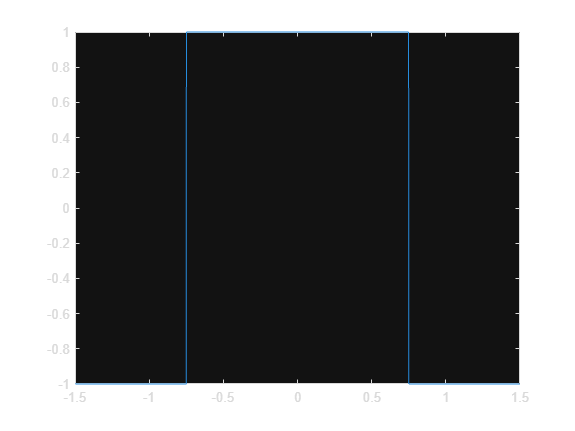

plot(t,f)

**Calculate Real-Valued Coefficients**

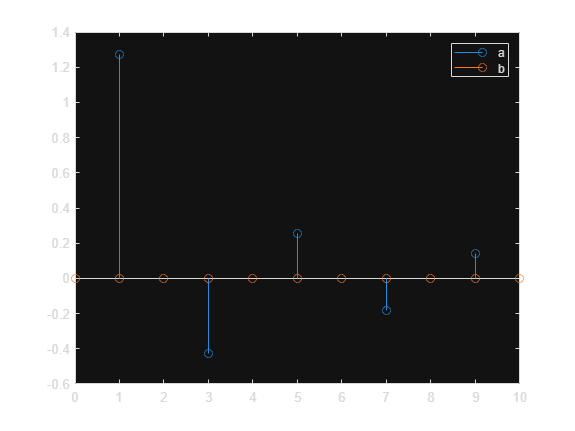

N = 10; %number of hamonic
a = zeros(1,N+1);
b = zeros(1,N+1);
for n= 0:N
    sum(f.*cos(2*pi*n*t/T));
    a(n+1) = (2*Ts/T)*sum(f.*cos(2*pi*n*t/T));
    b(n+1) = (2*Ts/T)*sum(f.*sin(2*pi*n*t/T));
end

stem(0:N,a)
hold on
stem(0:N,b)
hold off
legend('a','b')

**Fourier Series Sine/cosine Form**

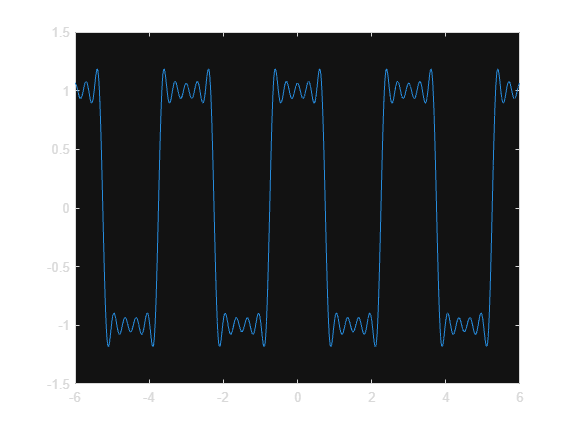

t=-2*T:Ts:2*T;
fs = (a(1)/2)*ones(size(t));

for n=1:N
    fs=fs+(a(n+1)*cos(2*pi*n*t/T))+(b(n+1)*sin(2*pi*n*t/T));
end
plot(t,fs)